clear all
close all
clc

% Known Parameters
a1 = 4; a2 = 3;
d1 = 7; d4 = 2;
K = pi/180;
P = [];

%win = [Xmin Xmax Ymin Ymax Zmin Zmax]
W = [-7.5 7.5 -7.5 7.5 -3 7]

W =    -7.5000    7.5000   -7.5000    7.5000   -3.0000    7.0000



% DH TABLE
% L = Link([theta d a alpha sigma R-->0, P-->1])
L1 = Link([0 d1 a1 0  0]);%Revolute
L2 = Link([0 0  a2 pi 0]);%Revolute
L3 = Link([0 0  0  0  1]);%Prismatic
L4 = Link([0 d4 0  0  0]);%Revolute

L1.qlim = [-180 +180]*K;% Link1 Limitation
L2.qlim = [-140 +140]*K;% Link2 Limitation
L3.qlim = [0 2.5];% Link3 Limitation
L4.qlim = [-270 +270];% Link4 Limitation

scara = SerialLink([L1 L2 L3 L4]);
scara.name = 'SCARA'

 
scara = 
 
SCARA (4 axis, RRPR, stdDH, fastRNE)                             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          7|          4|          0|          0|
|  2|         q2|          0|          3|      3.142|          0|
|  3|          0|         q3|          0|          0|          0|
|  4|         q4|          2|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1            

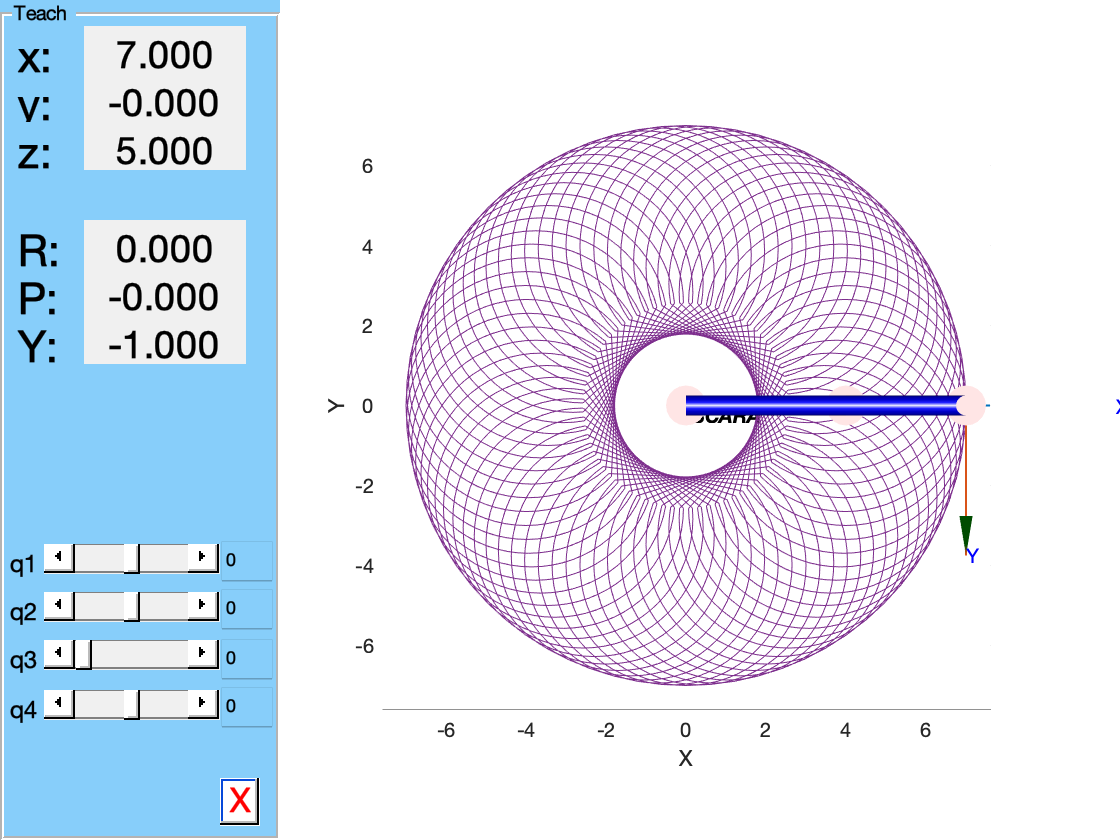


scara.plot([0 0 0 0],'workspace', W), hold on
scara.teach()

            A1 = scara.links(1).A(30*K); %value in b/w L1 limitation
            A2 = scara.links(2).A(60*K); %value in b/w L2 limitation
            A3 = scara.links(3).A(0.5); %value in b/w L3 limitation
            A4 = scara.links(4).A(0); % theta4 = 0

for q1 = -180 : 5 : +180 
    for q2 = -140 : 5 : +140
        for q3 = 0 : 0.1 : 2.5
            A1 = scara.links(1).A(q1*K);
            A2 = scara.links(2).A(q2*K);
            A3 = scara.links(3).A(q3);
            A4 = scara.links(4).A(0);
            T = A1*A2*A3*A4;
            P = [P; T(1:3,4)']; % Position
        end
    end
end

plot3(P(:,1),P(:,2),P(:,3))